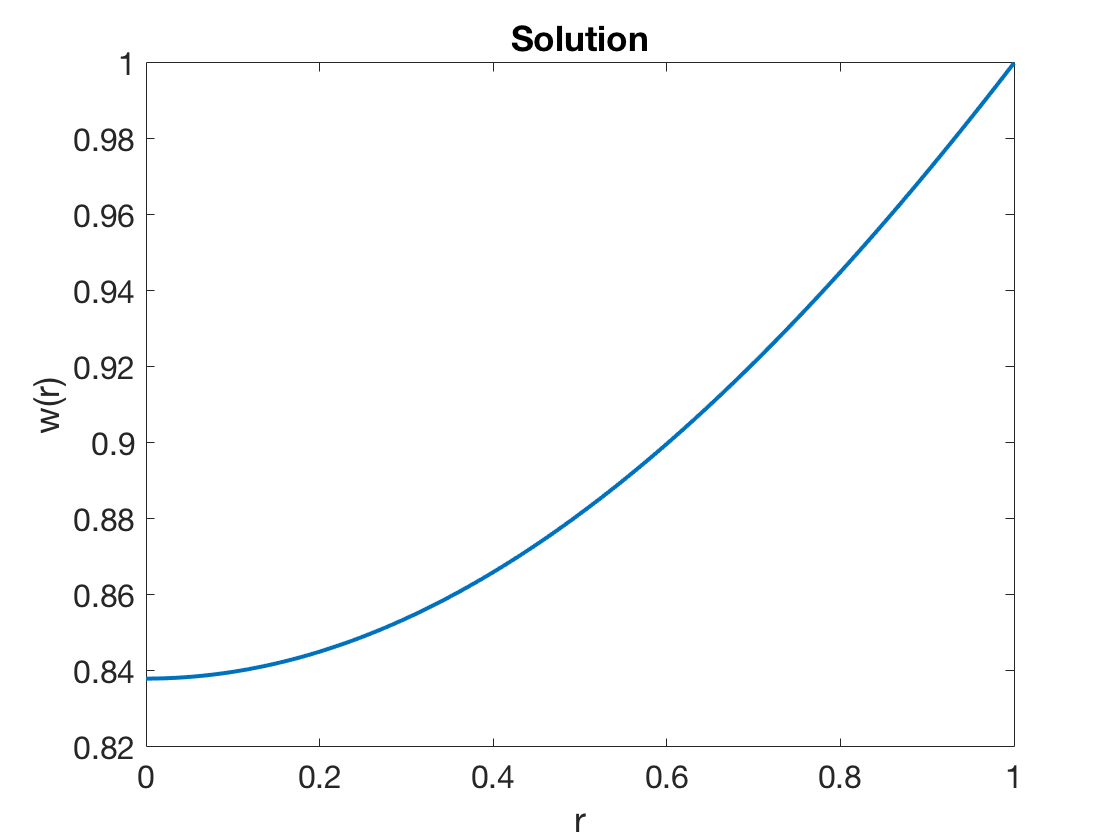

lambda = 0.5;
phi = @(r,w,dwdr) lambda./w.^2 - dwdr./r;
init = ones(301,1);
[r,w1] = bvp(phi,[0,1],[],0,1,[],init);
plot(r,w1)
xlabel('r'), ylabel('w(r)')   % ignore this line
title('Solution')   % ignore this line

By choosing a different initial guess, we arrive at another solution.

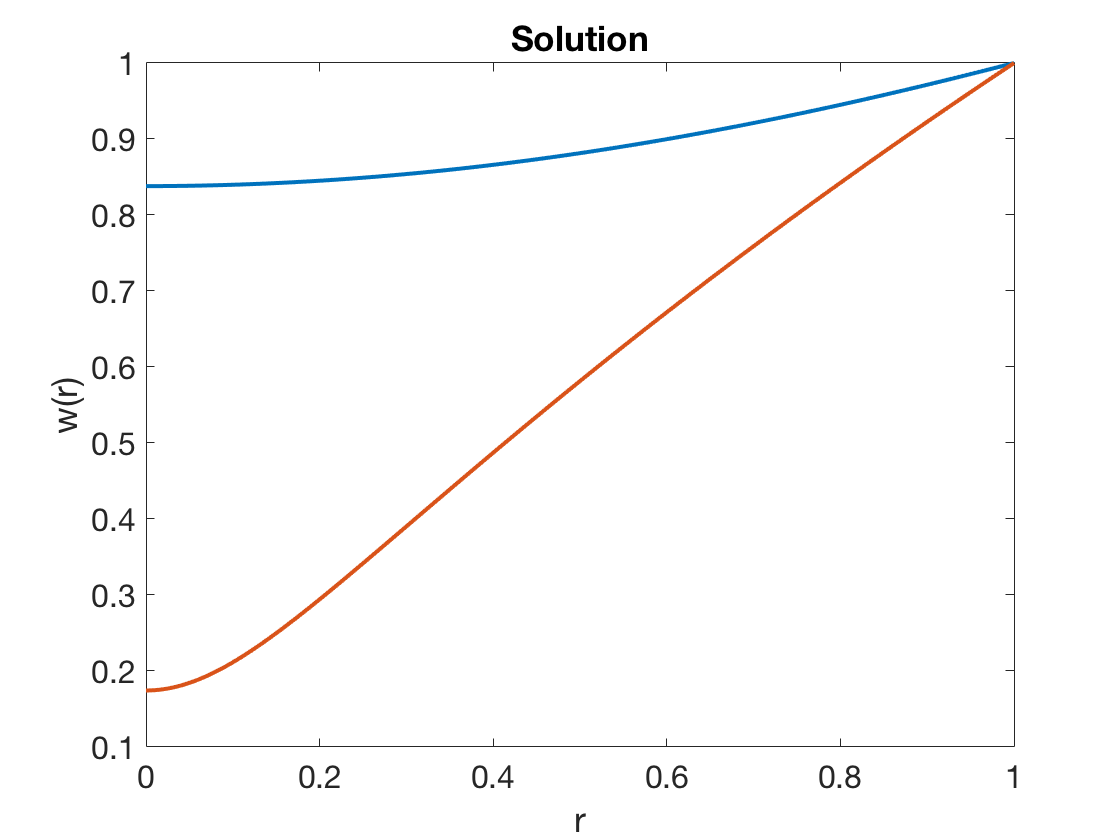

init = 0.5*ones(301,1);
[r,w2] = bvp(phi,[0,1],[],0,1,[],init);
hold on, plot(r,w2)